clear all


## initialize paramters

% number of modes
m = [1:10]; 
% inner radius
r1 = 1;
% outer radius
r2 = 2;
% discretization
n = 1000;
% steps
dr = (r2-r1)/n;
dtheta = 2*pi/n;
%variable vectors
theta = 0:dtheta:2*pi;
radius = r1:dr:r2;
% initializing solution u vector
u = zeros(n+1);


## solving for solution u

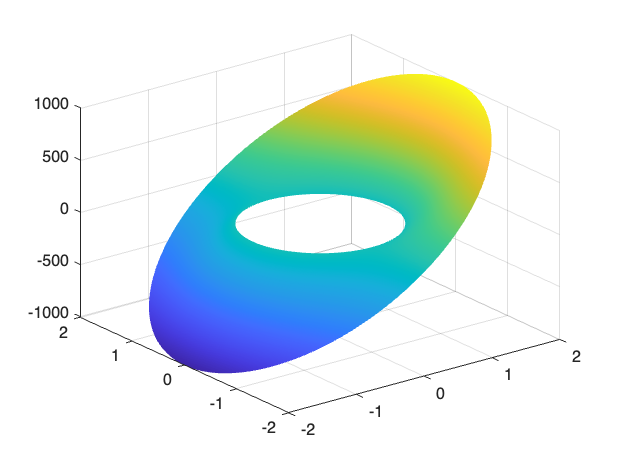

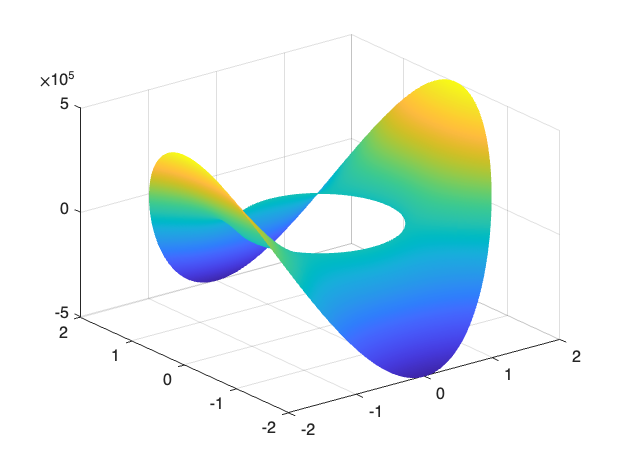

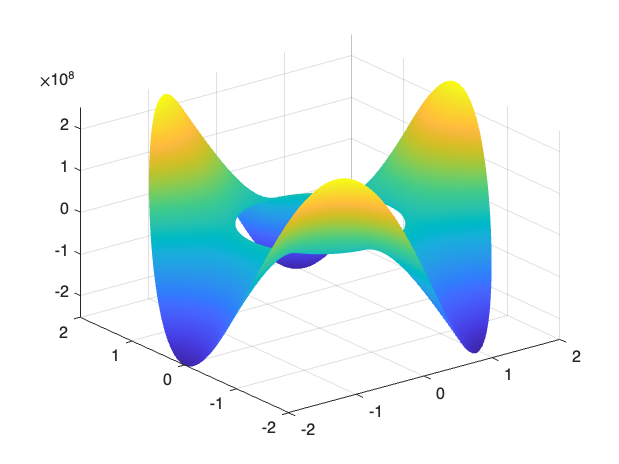

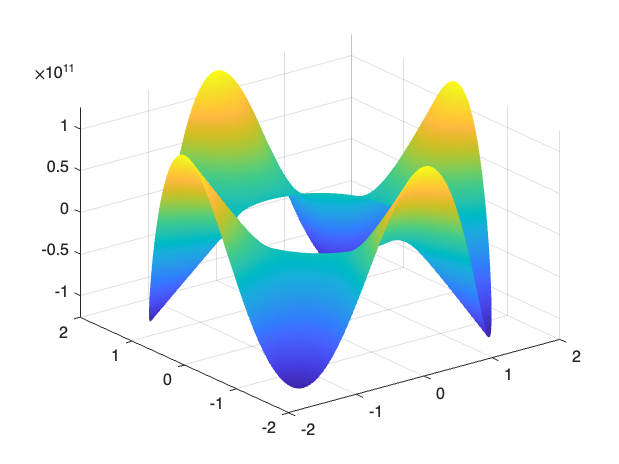

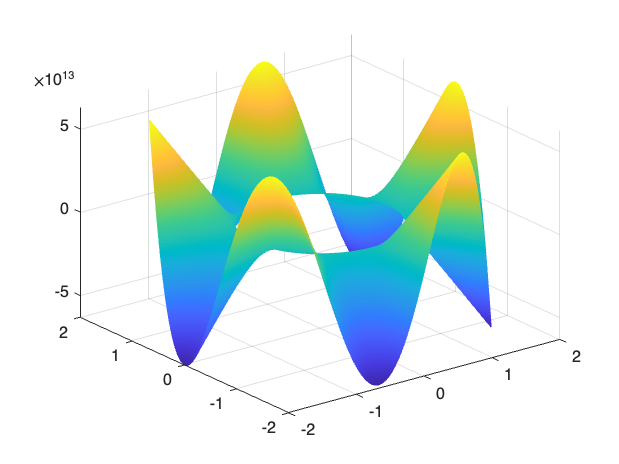

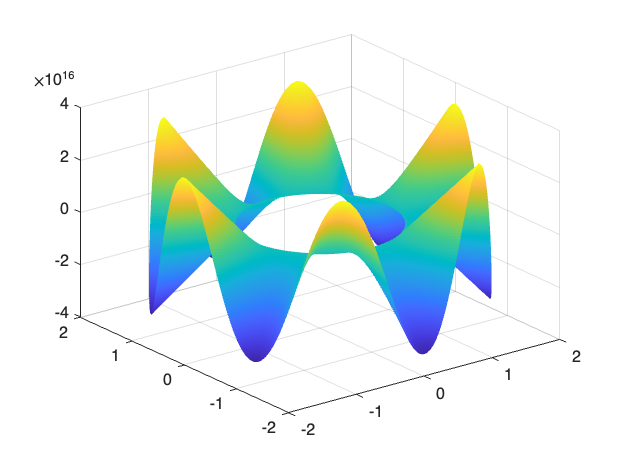

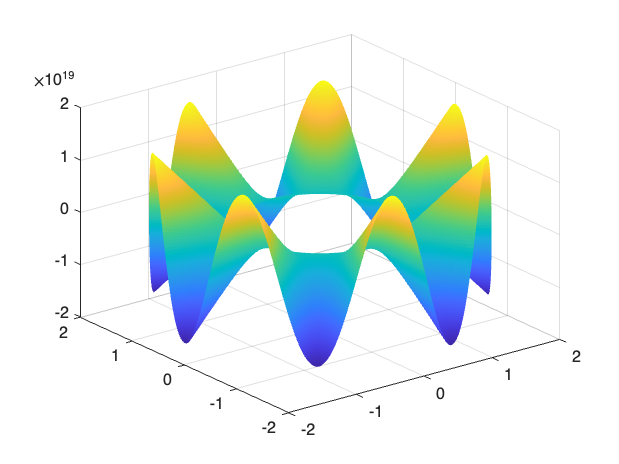

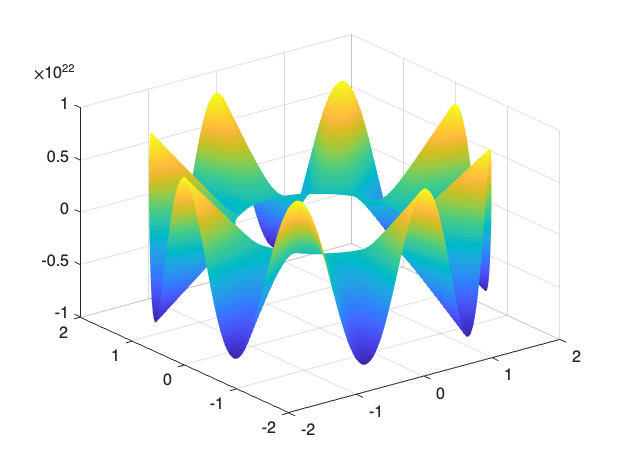

for l=1:length(m)
    figure
    [t,r] = meshgrid(theta,radius); 
    u = (((r-r1)/(r2-r1))^m(l))*cos(m(l)*t);
    [x,y] = pol2cart(t,r); 
    mesh(x,y,u)

end




    